clear; close all;

## Homework 4

## Problem 0: some fake data to mess with

t = linspace(0,100*pi,1e5);
N = 10 + sin(t);
bkgd = normrnd(0,1)* sqrt(N) + N;

## Problem 1: Subsets of Data

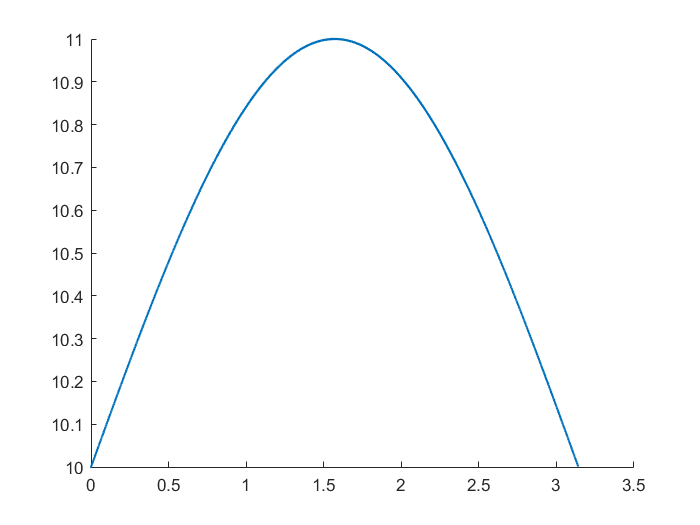

scatter(t(1:1000),N(1:1000),1);

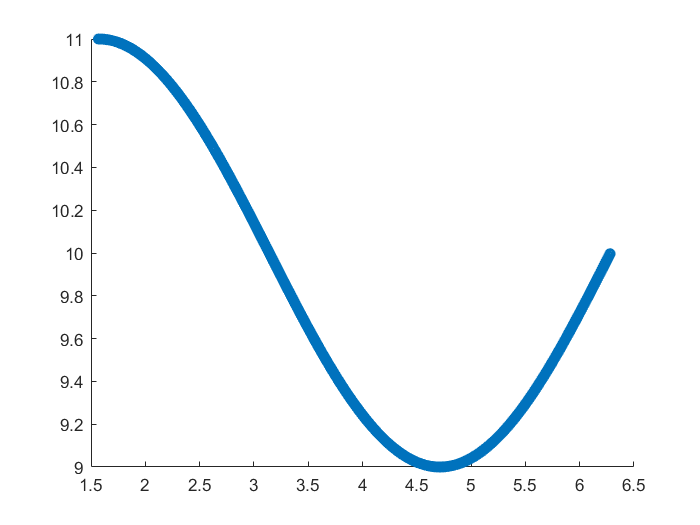


x1 = 500; x2 = 2000;
X = x1:x2;
scatter(t(X),N(X));

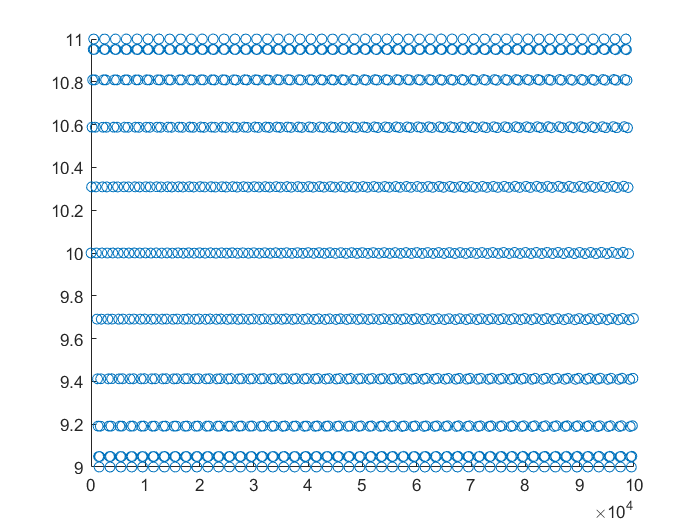


Y = 1:100:100000;
s = 1:numel(N);
scatter(s(Y),N(Y));

## Problem 2: Density

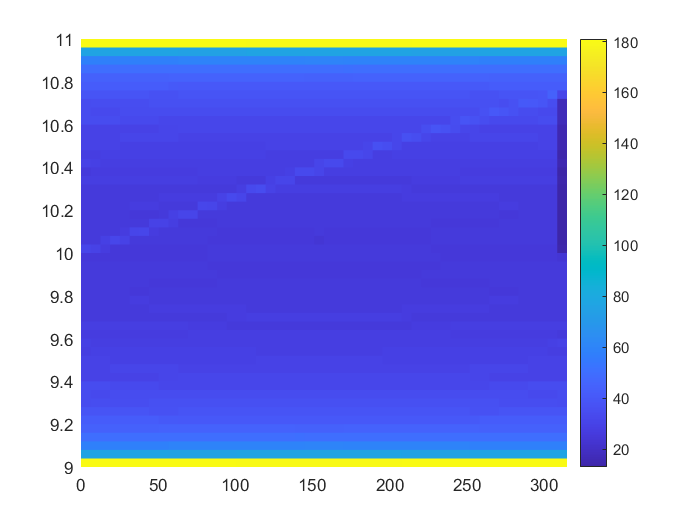

histogram2(t,N,50,'DisplayStyle','tile')
colorbar

From the 3D graph of the 2D histrogram you can see that the density increases on the edges of the plot and decreases as you come towards the center. There is a spike in the middle which is interesting.

## Problem 3: Folding

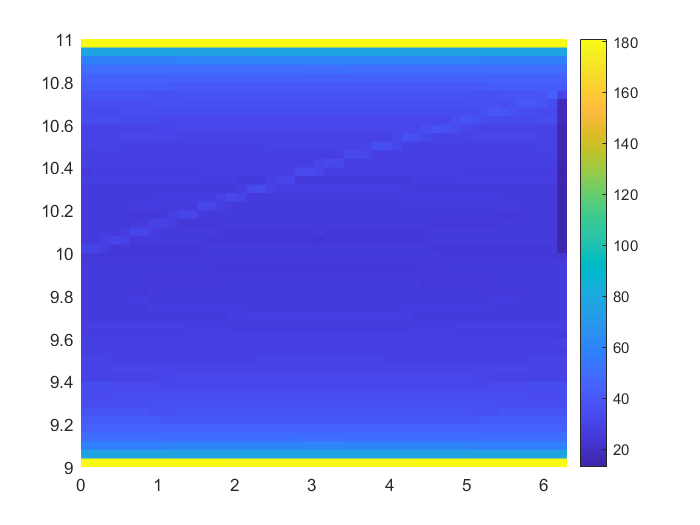

tnew = linspace(0,mod(2*pi,100*pi),1e5);
histogram2(tnew,N,50,'DisplayStyle','tile')
colorbar

% I couldn't figure this part out not sure what to do here